# Explore Trained Food Classification Network

This example shows how to use the attached supporting file '`UNPIC.mlapp`' to explore the predictions of a trained food classification network. 

Understanding Network Predictions for Image Classification (UNPIC) is an app to help you explore the classifications of a trained network. To get started, click **Run **  to run the example live script. This script will load example data, load a trained food classification network, and open the app so you can start exploring the predictions.

## Load Data

Download and extract the Example Food Image data set from [https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip](https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip).

rng default
dataDir = fullfile(tempdir,"ExampleFoodImageDataset");
url = "https://ssd.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip";

if ~exist(dataDir,"dir")
    mkdir(dataDir);
end

downloadExampleFoodImagesData(url,dataDir);

Skipping download, file already exists...
Skipping unzipping, file already unzipped...
Done.


Create an image datastore using the `imageDatastore` function.

imds = imageDatastore(dataDir, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imds.Labels = categorical(replace(string(imds.Labels),"_"," "));

Split the data into training and validation sets.

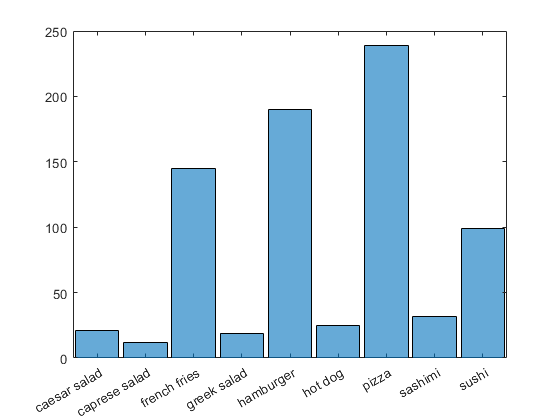

[imdsTrain, imdsVal] = splitEachLabel(imds,0.8,0.2,'randomized');
histogram(imdsTrain.Labels)

## Load Trained Network

Load the trained network into the workspace. 

load('trainedNet_Food.mat');
net = trainedNet;

To save time, this example uses a pretrained food image classification network. For an example showing how to train a classification network, see the supporting live script '`VisualizeTrainedNetworkExample.mlx`'.

## Open App with Trained Network

The UNPIC app requires a trained network and image data. This example uses the validation data to help explore what the trained network has learned.

UNPIC(trainedNet,imdsVal);

## Network Accuracy

Calculate the network accuracy on the validation data set. You can see that this network has greatest difficulty classifying hot dogs and Greek salad. These classes did not contain many images, therefore the lower accuracy might be as the network did not have enough information to learn how to accurately classify these types of food.

From the confusion matrix you can see that the network has difficulty distinguishing between sushi and sashimi. This is expected as images from these classes will share similar features, that are very different to the other classes such as hamburger or fries.

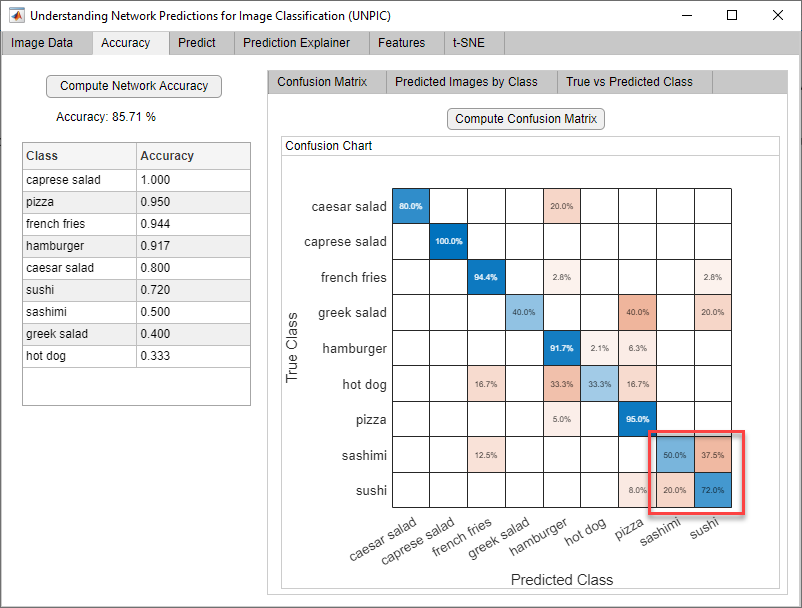

#### t-SNE Plot

Explore this further by displaying the t-SNE plot. You can see that the clusters for sushi and sashimi heavily overlap, illustrating that the network has difficulty in distinguishing the unique features of these classes. 

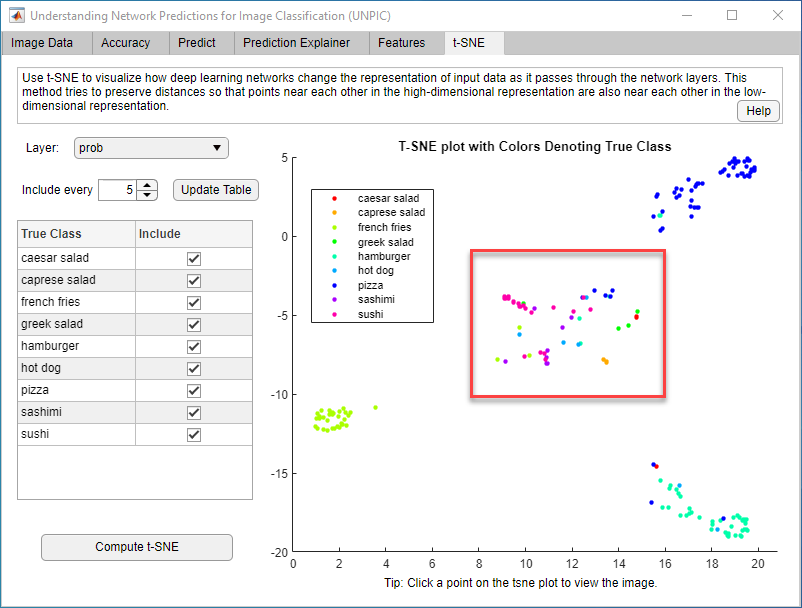

To view individual images, click the points on the t-SNE plot. Use this to better understand why certain images are misclassified. Focusing on the hamburger class, you can see points for images of other classes clustered together with the hamburger observations. This suggests that these images will be misclassified using the trained network. Clicking the images you can see that they are misclassified, additionally by inspecting the images you can gain an insight into why these images are misclassified as a hamburger. For example, the misclassified hot dog resembles the bun-meat-bun structure of a hamburger.

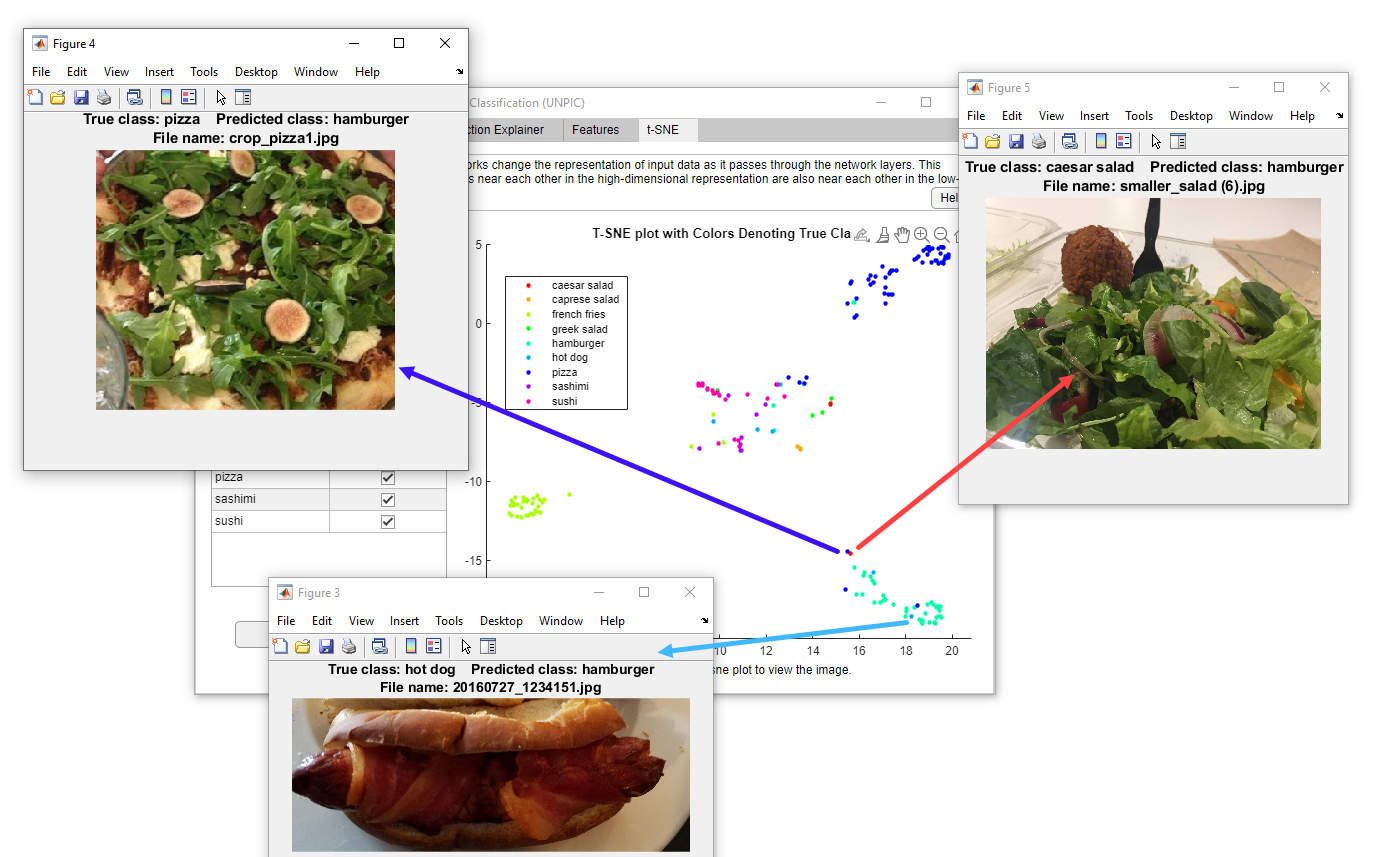

## Network Predictions

Take a closer look at the network predictions. You can see that although pizza has a high accuracy there is an incorrectly classified image. 

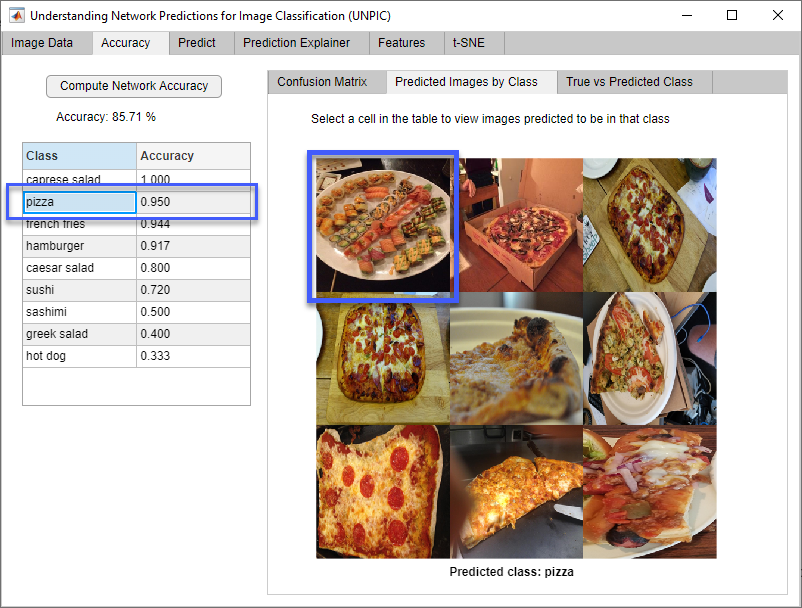

Exploring further you can see images that are true class sushi but incorrectly classified as pizza. This can help you to understand when a network fails to correctly classify an image. Here you can see that the sushi is arranged in such a way as to confuse the network into classifying it as a pizza.

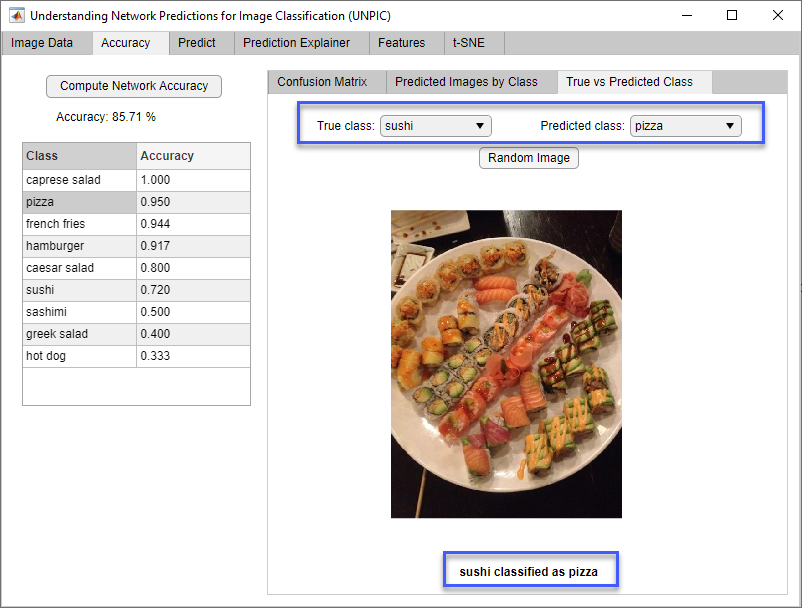

## Network Explainers

Use explainers to investigate why an image is predicted as certain class. Consider the image below containing a Caesar salad. This image has been incorrectly classified as a hamburger. Why did the network decide this is a hamburger?

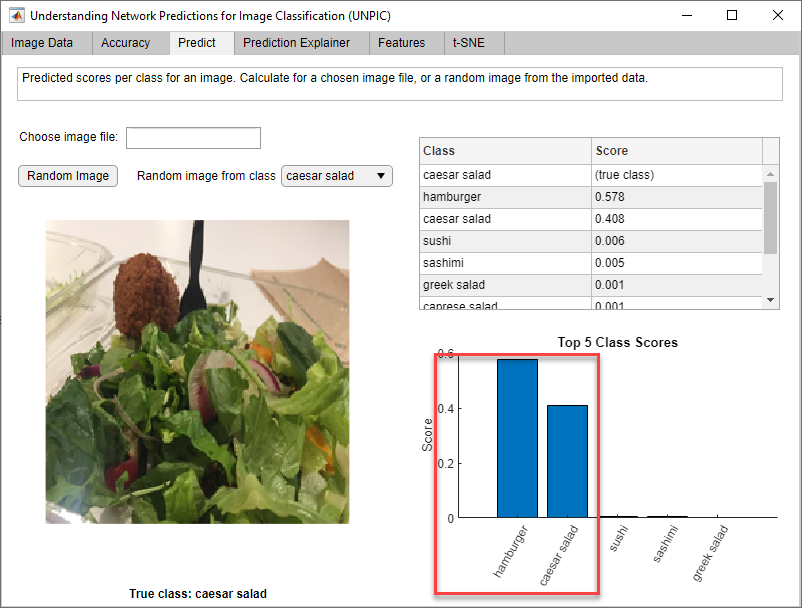

By displaying the Grad-CAM you can see the features that activate strongly for each class. Setting the target class as caesar salad the network correctly picks out the salad in the image.

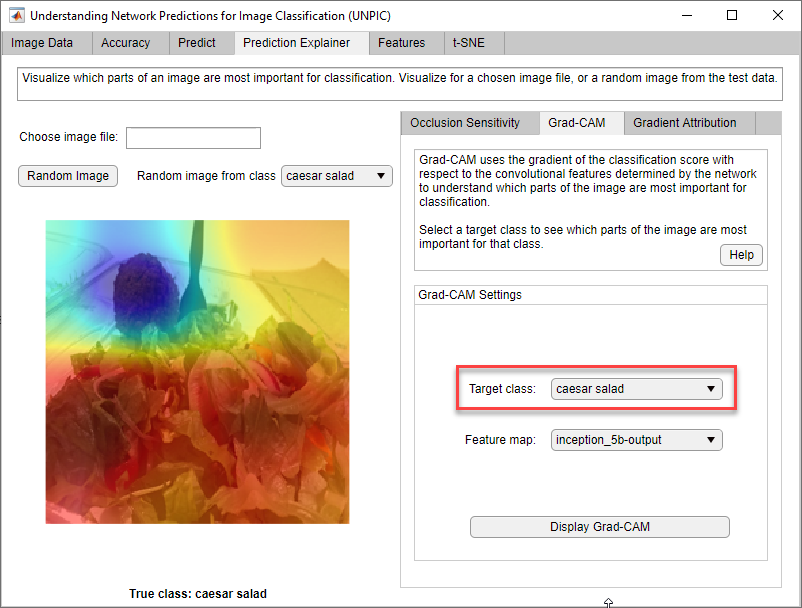

Setting the target class to hamburger you can see why the network has incorrectly classified this image. The image is highly activating for class hamburger on the falafel in the image. The falafel has confused the network and it has incorrectly classified this image as containing a hamburger. 

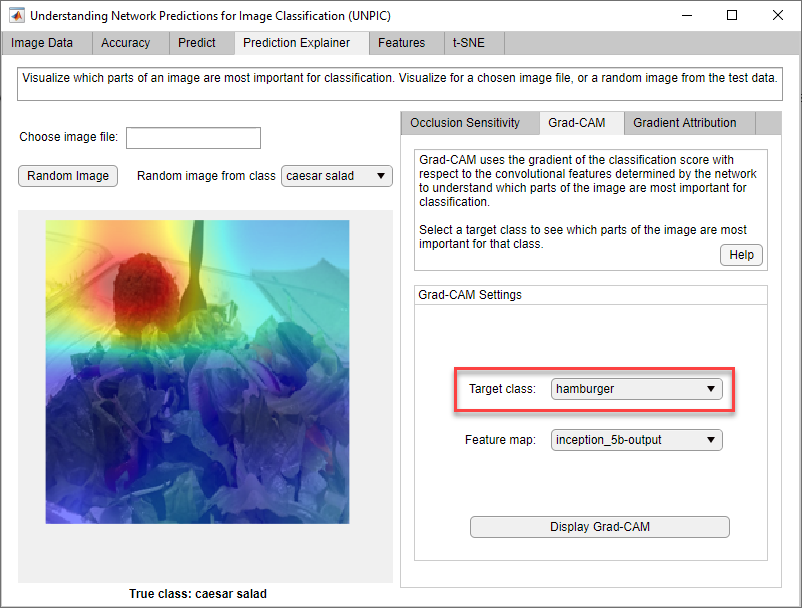

Discovery such as this is important for understanding what a network has learned. You can then use this information to help improve the accuracy of the network.

## Helper Function

function downloadExampleFoodImagesData(url,dataDir)
% Download the Example Food Image data set, containing 978 images of
% different types of food split into 9 classes.

% Copyright 2019 The MathWorks, Inc.

fileName = "ExampleFoodImageDataset.zip";
fileFullPath = fullfile(dataDir,fileName);

% Download the .zip file into a temporary directory.
if ~exist(fileFullPath,"file")
    fprintf("Downloading MathWorks Example Food Image dataset...\n");
    fprintf("This can take several minutes to download...\n");
    websave(fileFullPath,url);
    fprintf("Download finished...\n");
else
    fprintf("Skipping download, file already exists...\n");
end

% Unzip the file.
%
% Check if the file has already been unzipped by checking for the presence
% of one of the class directories.
exampleFolderFullPath = fullfile(dataDir,"pizza");
if ~exist(exampleFolderFullPath,"dir")
    fprintf("Unzipping file...\n");
    unzip(fileFullPath,dataDir);
    fprintf("Unzipping finished...\n");
else
    fprintf("Skipping unzipping, file already unzipped...\n");
end
fprintf("Done.\n");

end

## References 

[1] *BVLC GoogLeNet Model*. [https://github.com/BVLC/caffe/tree/master/models/bvlc_googlenet](https://github.com/BVLC/caffe/tree/master/models/bvlc_googlenet)

*Copyright 2020 The MathWorks, Inc.*